# Hands on 3: 1.3

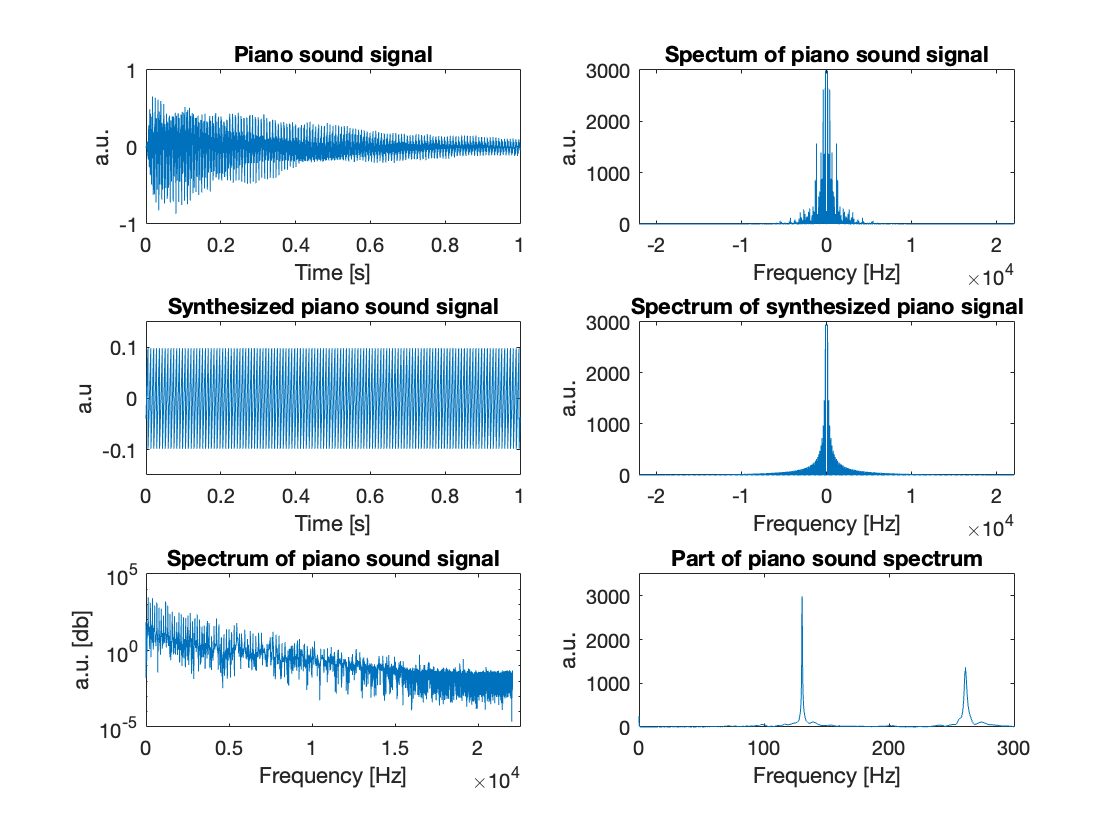

% Load data:
[y, fs]  = audioread('piano.wav');
timeVector = 0:1/fs:length(y)/fs-1/fs;

% Plot data:
hold on
subplot(3, 2, 1)
plot(timeVector, y)
xlim([0, 1])
title('Piano sound signal')
xlabel('Time [s]')
ylabel('a.u.')
hold off

% Compute the fourier transform of the signal:
Y = fft(y);
Y = fftshift(Y);
N = length(y);
delta_f = fs/N;
freq = -fs/2:delta_f:fs/2-delta_f;

% PLot the spectrum of the original signal:
hold on
subplot(3, 2, 2)
plot(freq, abs(Y))
title('Spectum of piano sound signal')
xlabel('Frequency [Hz]')
ylabel('a.u.')
hold off

% Plot the whole spectrum of the signal:
subplot(3, 2, 5)
semilogy(freq(freq > 0), abs(Y(freq > 0)))
xlim([0, 22500])
title('Spectrum of piano sound signal')
xlabel('Frequency [Hz]')
ylabel('a.u. [db]')

% Plot to find the fundamental frequency:
subplot(3, 2, 6)
plot(freq, abs(Y))
xlim([0, 300])
ylim([0, 3500])
title('Part of piano sound spectrum')
xlabel('Frequency [Hz]')
ylabel('a.u.')

% Synthezise
T = 5;
f0 = 130;
delta_f_syn = 1/2;
freq_syn = -fs/2:delta_f_syn:fs/2-delta_f_syn;
Y_syn = zeros([1, length(freq_syn)]);

for k = 1:169
    [~, posIdx_f0] = min(abs(freq_syn - (f0 * k)));
    [~, negIdx_f0] = min(abs(freq_syn - (-f0 * k)));
    Y_syn(posIdx_f0) =  1 / (2 * 1i);
    Y_syn(negIdx_f0) = -1 / (2 * 1i);
end

% Transform back to time domain:
Y_syn = ifftshift(Y_syn);
y_syn = ifft(Y_syn);
timeVector = 0:1/fs:length(y_syn)*1/fs - 1/fs;

%sound(abs(y_syn*1000), fs)

% Now synthesize including phase and amplitude:
Y_syn = zeros([1, length(freq_syn)]);

for k = 1:169
    [~, posIdx_f0] = min(abs(freq_syn - (f0 * k)));
    [~, negIdx_f0] = min(abs(freq_syn - (-f0 * k)));
    
    Y_syn(posIdx_f0) = (35 - 35 * 22050 / (k*f0)) ...
            * (1 / (2 * 1i)) ...
            * exp(-(0.13 * 1i) * f0 * k);
    
    Y_syn(negIdx_f0) = (35 - 35 * 22050 / (k*f0)) ...
            * (-1 / (2 * 1i)) ...
            * exp(-(0.13 * 1i) * (-f0) * k);
end

% Plot the specturm om the synthesized signal:
hold on
subplot(3, 2, 4)
plot(freq_syn, abs(Y_syn))
title('Spectrum of synthesized piano signal')
xlabel('Frequency [Hz]')
ylabel('a.u.')
hold off

% Transform back to time domain:
Y_syn = ifftshift(Y_syn);
y_syn = ifft(Y_syn);

%sound(y_syn, fs)
%sound(y, fs)

% Plot the synthesized piano signal:
hold on
subplot(3, 2, 3)
plot(timeVector, y_syn)
title('Synthesized piano sound signal')
xlim([0,1])
ylim([-0.15, 0.15])
xlabel('Time [s]')
ylabel('a.u')
hold off